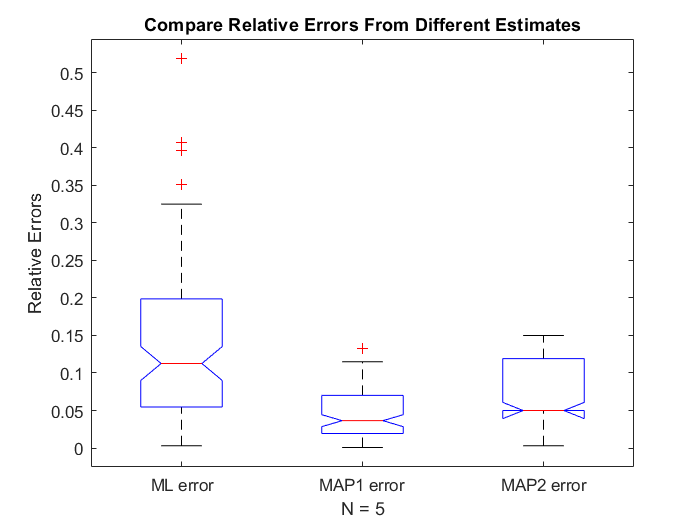

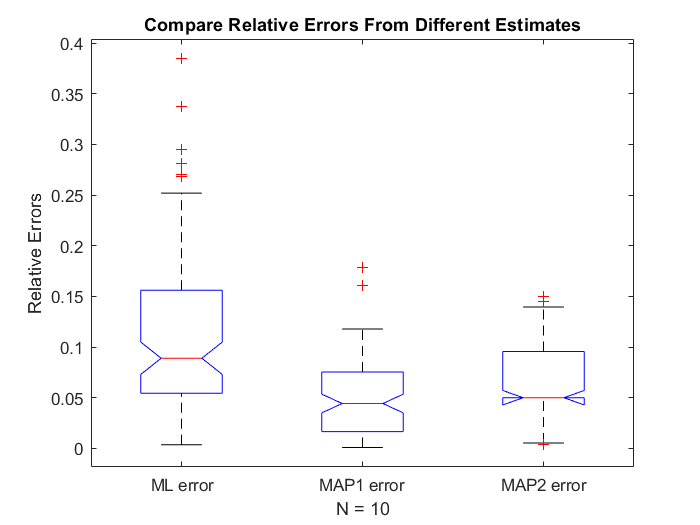

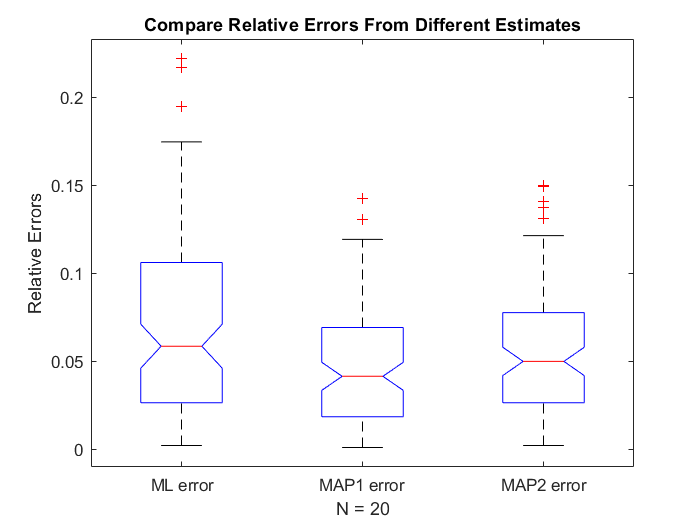

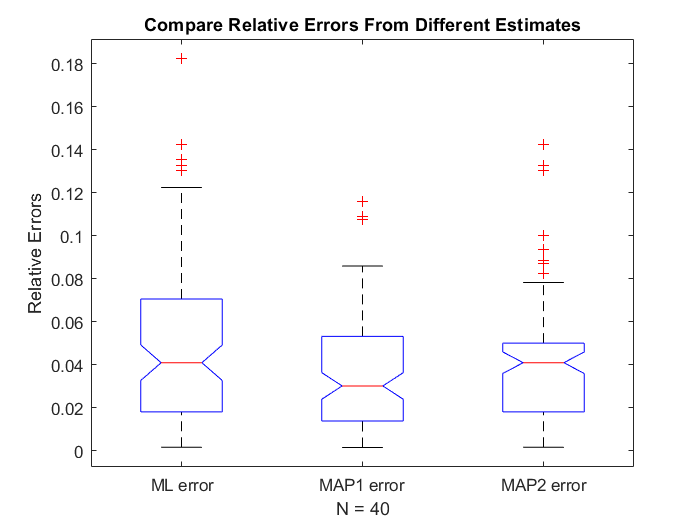

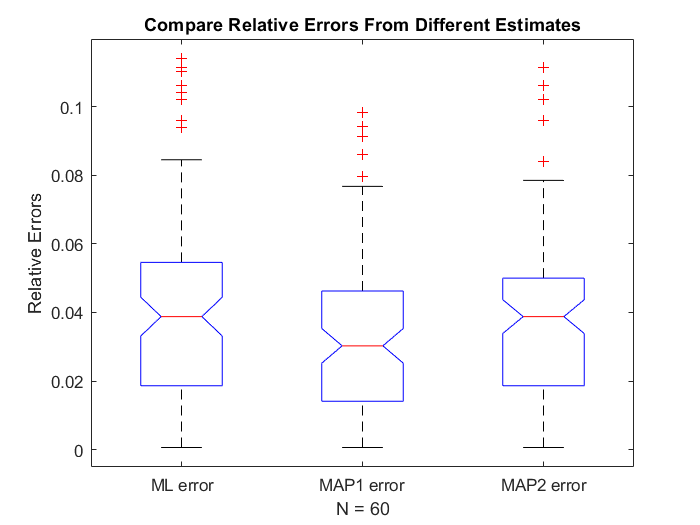

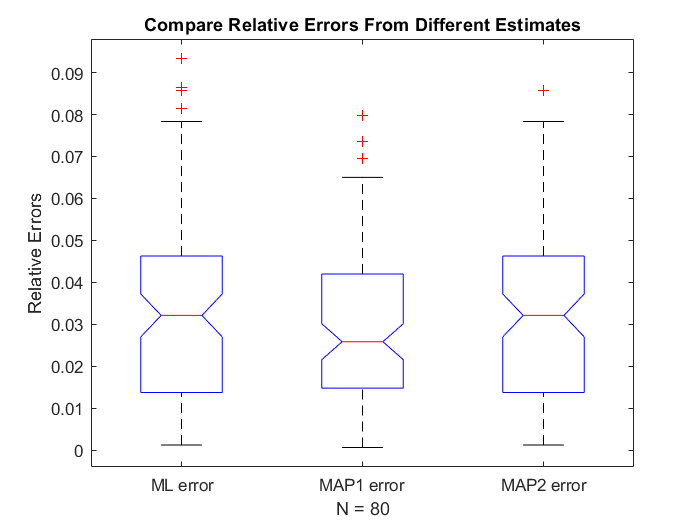

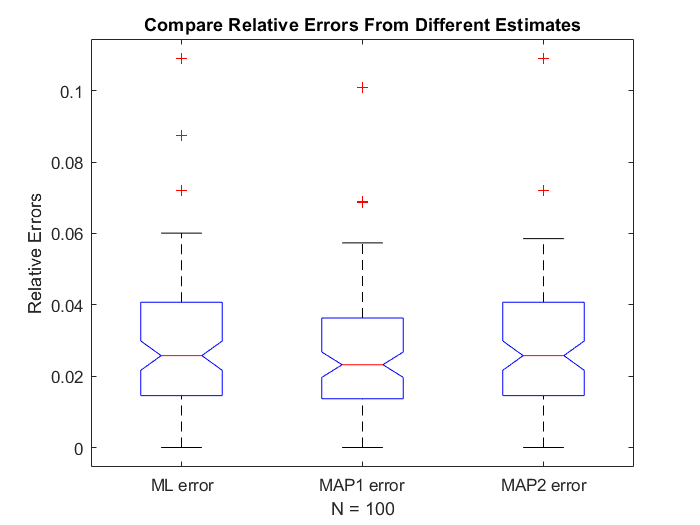

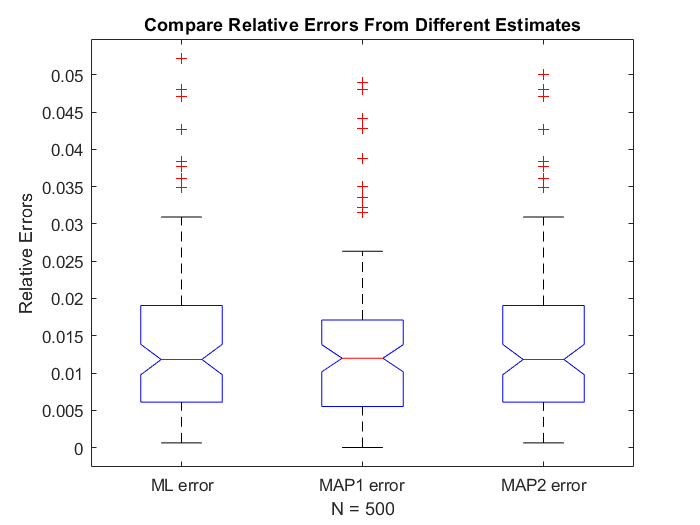

rng("default")

N = [5, 10, 20, 40, 60, 80, 100, 500, 1000 10000]; % Sizes of the different datasets
m = 100; % Number of times an experiment is repeated
errors_ML = zeros(m,10);
errors_MAP1 = zeros(m,10);
errors_MAP2 = zeros(m,10);
for j = 1:10
    n = N(j); % The size of dataset being used
    mean_true = 10; % The given true mean
    standard_deviation_true = 4; % The given true standard deviation
    var_true = standard_deviation_true^2; % The true variance
    error_ML = zeros(m,1); % Stores error values of ML estimate
    error_MAP1 = zeros(m,1); % Stores error values of MAP1 estimate
    error_MAP2 = zeros(m,1); % Stores error values of MAP2 estimate
    for i = 1:m
        data = standard_deviation_true*randn(1,n)+mean_true; % Generating the random data with given true mean and standard_deviation
        
        % Finding the sample mean
        sample_mean = sum(data)/n;
        % Finding the ML estimate which is equal to sample mean for gaussian distribution
        mean_ML = sample_mean;
        
        % Considering a gaussian prior for the mean with mean 10.5 and standard deviation 1
        mean_0 = 10.5;
        standard_deviation_0 = 1; 
        var_0 = standard_deviation_0^2;
        
        % Using the formula for the Maximum A Posteriori estimate for this case: 
        mean_MAP1 = (sample_mean*var_0 + mean_0*var_true/n)/(var_true/n + var_0); 
        
        % Considering an uniform prior for the mean over 9.5 to 11.5 For an uniform prior the Posterior estimate:
        
        % The MAP estimate turns out to be sample mean if sample mean lies
        % between 9.5 and 11.5 else it turns out to be 9.5 if it is lesser
        % or 11.5 if it is greater
        if (sample_mean < 9.5)
            mean_MAP2 = 9.5;
        elseif(sample_mean < 11.5)
            mean_MAP2 = sample_mean;
        else
            mean_MAP2 = 11.5;
        end

        % Calculating and storing the relative values of the errors
        error_ML(i,1) = abs(mean_ML - mean_true)/mean_true;
        error_MAP1(i,1) = abs(mean_MAP1-mean_true)/mean_true;
        error_MAP2(i,1) = abs(mean_MAP2 - mean_true)/mean_true;
    end

    % Making the boxplots of the errors for different values of the dataset size
    figure
    boxplot([error_ML,error_MAP1,error_MAP2],'Notch','on','Labels',{'ML error','MAP1 error','MAP2 error'},'Whisker',1)
    title(sprintf('Compare Relative Errors From Different Estimates'))
    xlabel(sprintf('N = %d',n))
    ylabel('Relative Errors')
    errors_ML(:,j) = error_ML;
    errors_MAP1(:,j) = error_MAP1;
    errors_MAP2(:,j) = error_MAP2;
end

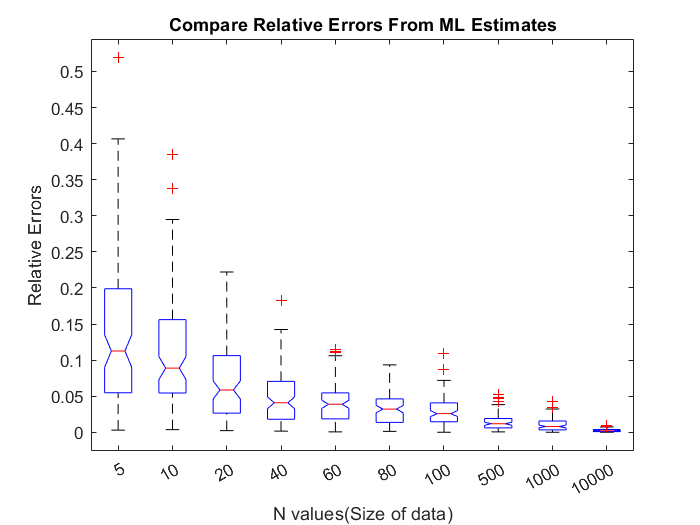

% Plotting only the ML errors for different values of N 
figure 
boxplot(errors_ML,'Notch','on','Labels',N)
title(sprintf('Compare Relative Errors From ML Estimates'))
xlabel(sprintf('N values(Size of data)'))
ylabel('Relative Errors')

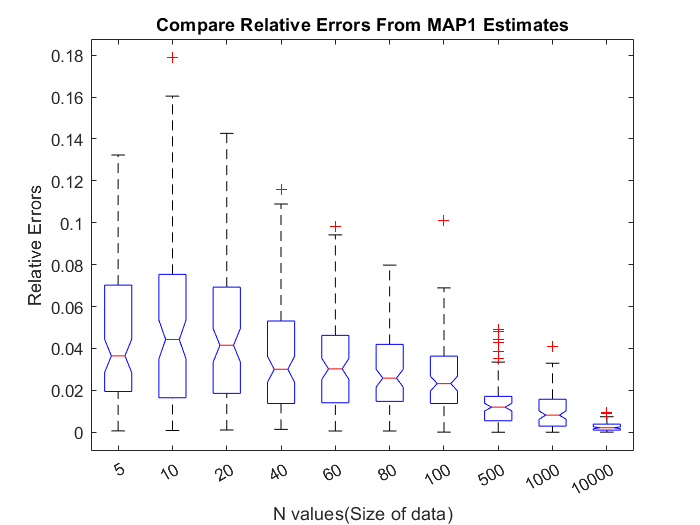

% Plotting only the MAP1 errors for different values of N 
figure 
boxplot(errors_MAP1,'Notch','on','Labels',N)
title(sprintf('Compare Relative Errors From MAP1 Estimates'))
xlabel(sprintf('N values(Size of data)'))
ylabel('Relative Errors')

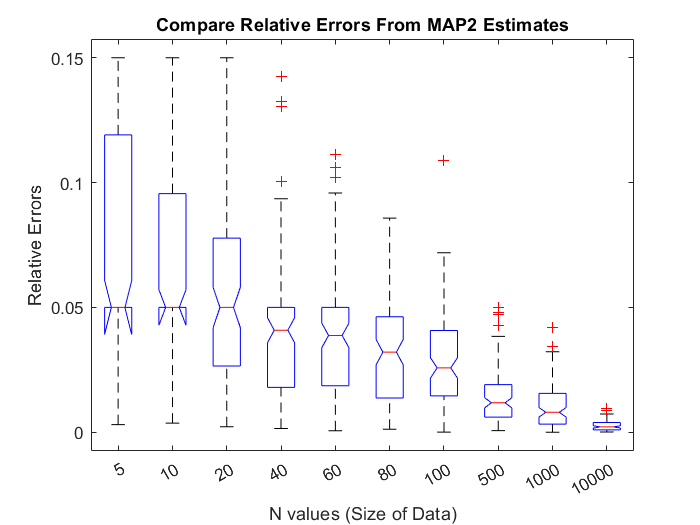

% Plotting only the MAP2 errors for different values of N 
figure 
boxplot(errors_MAP2,'Notch','on','Labels',N)
title(sprintf('Compare Relative Errors From MAP2 Estimates'))
xlabel(sprintf('N values (Size of Data)'))
ylabel('Relative Errors')

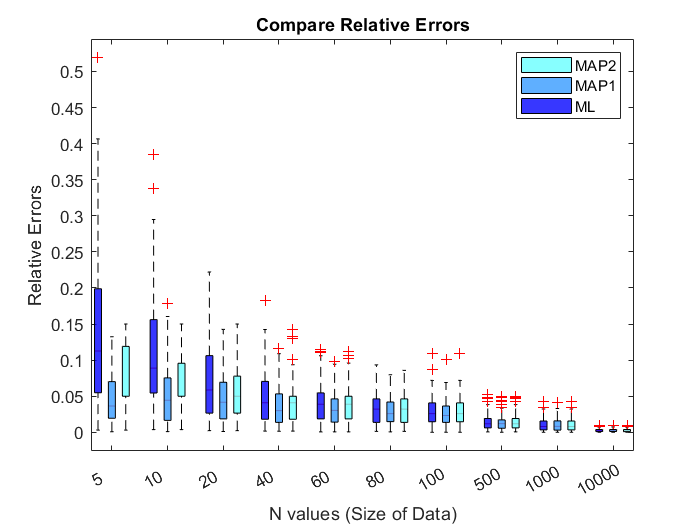

% Plotting all the three errors together for different values of N 
figure
data=cell(10,3);
for ii=1:size(data,1)
Ac{ii}=errors_ML(:,ii);
Bc{ii}=errors_MAP1(:,ii);
Cc{ii}=errors_MAP2(:,ii);
end
data=vertcat(Ac,Bc,Cc);
xlab=N;
col=[102,255,255, 200;
51,153,255, 200;
0, 0, 255, 200];
col=col/255;
multiple_boxplot(data',xlab,{'ML', 'MAP1', 'MAP2'},col')
xlabel('N values (Size of Data)');
ylabel('Relative Errors');
title('Compare Relative Errors')